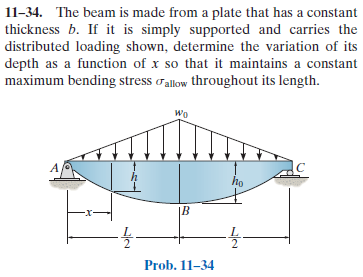

# distributed load formulas

wo = sym('wo');
L = sym('L');
wf1 = findpoly(1, 'thru', [0 0], [L/2 -wo]);
wf2 = findpoly(1, 'thru', [L/2 -wo], [L 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rc', L);
b = b.add('distributed', 'force', wf1, [0 L/2], [true false]);
b = b.add('distributed', 'force', wf2, [L/2 L]);

# section properties

B = sym('B');
Ho = sym('Ho');
H = sym('H');
b.I = B*H^3/12;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,{\left(5\,L^{2}-4\,x^{2}\right)}^{2}}{80\,B\,\text{E}\,H^{3}\,L} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L-x\right)\,{\left(L^{2}+8\,L\,x-4\,x^{2}\right)}^{2}}{80\,B\,\text{E}\,H^{3}\,L} & \text{ if }L<2\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(L+2\,x\right)\,\left(5\,L^{2}-4\,x^{2}\right)}{16\,B\,\text{E}\,H^{3}\,L} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(3\,L-2\,x\right)\,\left(L^{2}+8\,L\,x-4\,x^{2}\right)}{16\,B\,\text{E}\,H^{3}\,L} & \text{ if }L<2\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,x\,\left(3\,L^{2}-4\,x^{2}\right)}{12\,L} & \text{ if }2\,x<L\\ -\frac{\mathrm{wo}\,\left(L-x\right)\,\left(L^{2}-8\,L\,x+4\,x^{2}\right)}{12\,L} & \text{ if }L\leq 2\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(L+2\,x\right)}{4\,L} & \text{ if }2\,x<L\\ \frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(3\,L-2\,x\right)}{4\,L} & \text{ if }L\leq 2\,x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{2\,\mathrm{wo}\,x}{L} & \text{ if }2\,x<L\\ -\frac{2\,\mathrm{wo}\,\left(L-x\right)}{L} & \text{ if }L\leq 2\,x \end{array}\right.$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = \frac{L\,\mathrm{wo}}{4}$$

Rc = r.Rc %#ok

$$Rc = \frac{L\,\mathrm{wo}}{4}$$

clear Ra Rc;

# shear and moment diagram

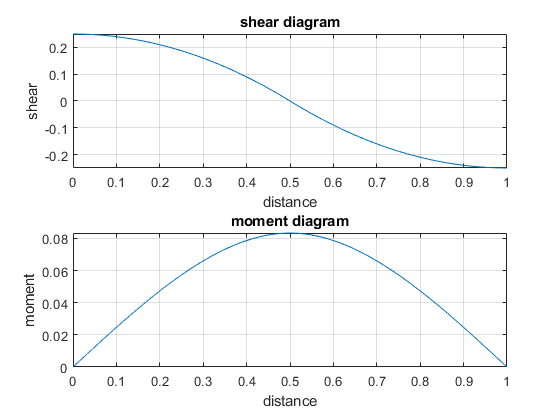

beam.shear_moment(m, v, [0 1], [wo L], 1);

# depth variation H

C = H/2;
sigma_max(x) = expression(m*C/b.I, 1);
Hfun = solve(subs(sigma_max(L/2), H, Ho) == sigma_max, H);
Hfun(x) = combine(Hfun(1), 'IgnoreAnalyticConstraints', true);